# Cleanup

clearvars
close all
clc

## Generate cuboid beacon

n_points = 8;
points = [25 25 35 35 25 25 35 35; 25 25 25 25 35 35 35 35; 8 4 8 4 8 4 8 4] * 0.5;
center = mean(points, 2);

## Plot beacon features

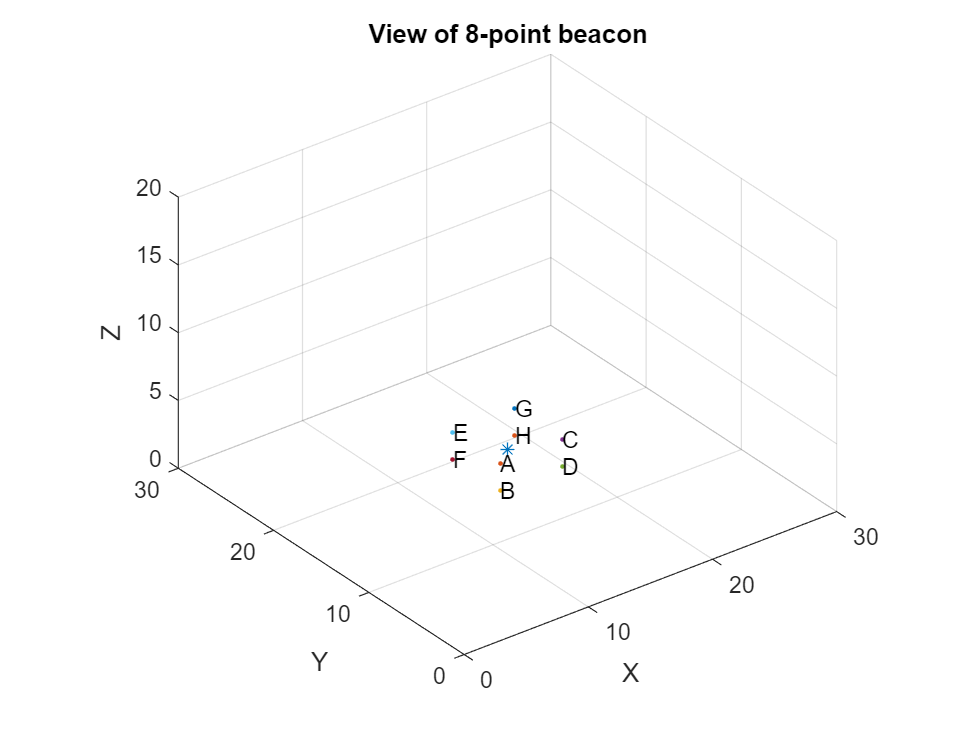

fig = figure('name', 'beacon');
scatter3(center(1), center(2), center(3), 'Marker', '*', 'HandleVisibility','off');
hold on
for  j = 1:n_points
    scatter3(points(1,j), points(2,j), points(3,j) , 'Marker' , '.', 'HandleVisibility','off');
    text(points(1,j), points(2,j), points(3,j), char('@'+ j));
    hold on;
end
title("View of " + n_points + "-point beacon")
axis equal
xlabel 'X'
ylabel 'Y'
zlabel 'Z'
xlim([0 30])
ylim([0 30])
zlim([0 20])

## Parameters

r0 = 15;
x0 = center(1);
y0 = center(2) - r0;
z0 = center(3);
N = 13; % N of photos
gamma_E = 0.05; % uniform noise coefficient for E poison
gamma_photo = 0.01; % uniform noise coefficient for photos

## Run Simulink

USE_SIMULINK = true;
radius_tolerance = 0.8; % determines when to start considering circular motion

if ~USE_SIMULINK
    %% Simulate running the script, and you get coords_x,coords_y,thetas as variables
    disp("Generating trajectory manually")
    n_samples = 1000;
    thetas = (0:1/n_samples:1 - 1/n_samples) * 360;
    circle = center + [r0 * cos(deg2rad(thetas)); r0 * sin(deg2rad(thetas)); zeros(1, n_samples)];
    coords_x = circle(1, :);
    coords_y = circle(2, :);
else
    %% Otherwise just filter input data
    disp("Using simulink simulation")
    %run def_trajectory.m
    load data.mat
    coords_x = x_out';
    coords_y = y_out';
    n_samples = length(coords_x);
    %% Find start of circular motion
    for i = 1:n_samples
        curr_norm = norm(coords_x(i), coords_y(i));
        if curr_norm > radius_tolerance * r0
            start_sample = i;
            break;
        end
    end
    coords_x = coords_x + center(1);
    coords_y = coords_y + center(2);
    coords_z = ones(1, n_samples)*center(3);
    thetas = rad2deg(theta_out(start_sample:end))';
    n_samples = length(coords_x) - start_sample + 1;
    seg_coords_x = coords_x(:,start_sample:end);
    seg_coords_y = coords_y(:,start_sample:end);
    seg_coords_z = center(3) * ones(1, n_samples);
end

Using simulink simulation


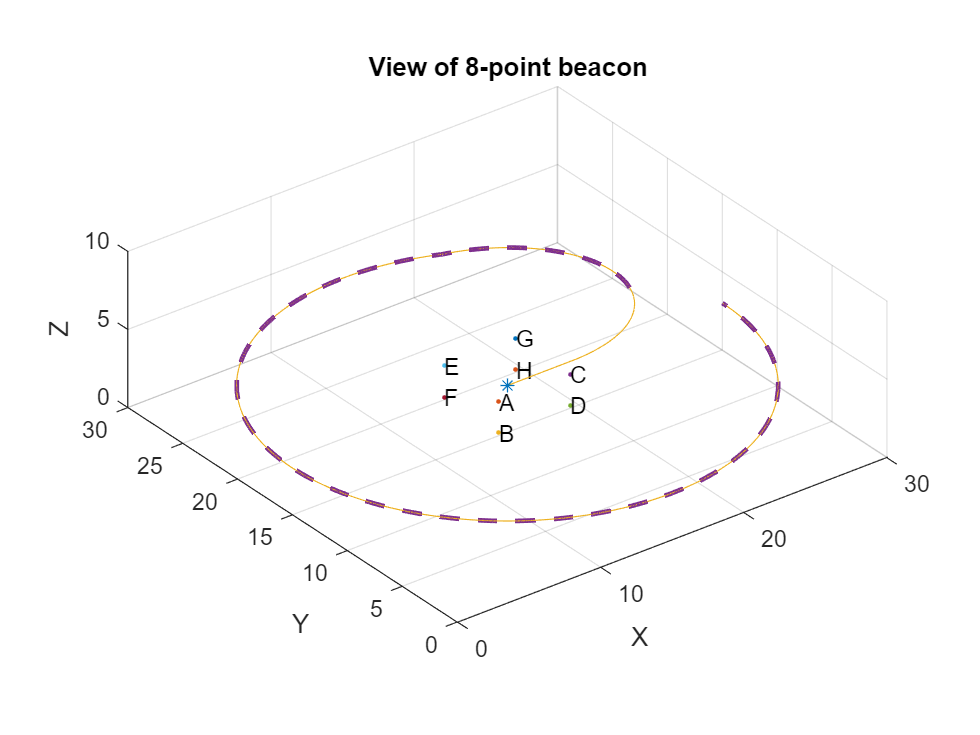

grid on
axis equal
hold on
plot3(center(1) + x_out', center(2) + y_out', coords_z)
plot3(seg_coords_x, seg_coords_y, seg_coords_z, "--", "LineWidth", 2)
view(3)
zlim([0 10])

## Get absolute measurements (T, R) from cartesian points

shoots_interval = ceil(n_samples / N);
saggi_angles = thetas(1:shoots_interval:end);
saggi_angles = wrapTo360(saggi_angles);
T_history_abs = [seg_coords_x(1:shoots_interval:end); seg_coords_y(1:shoots_interval:end); z0 * ones(1,N)];
%% Calculate the pose of camera wrt absolute frame
R_history_abs = zeros(3,3,N);
cam_angles = zeros(1,N);
for i = 1:N
    R_history_abs(:, :, i) = getRfromZ(T_history_abs(:,i), center);
    m = rotm2eul(R_history_abs(:,:,i));
    cam_angles(i) = wrapTo360(rad2deg(m(1)) + 90);
end
delta_cam_sag = wrapTo360(cam_angles - saggi_angles);

## Trajectory parameters

Rwb = R_history_abs(:,:,1); % Initial pose of camera (body 2 word)
Rbw = Rwb'; % Initial pose of camera (word 2 body)
Twb = T_history_abs(:,1,1); % Initial position of camera
Tbw = -Twb;

## Initial position plot

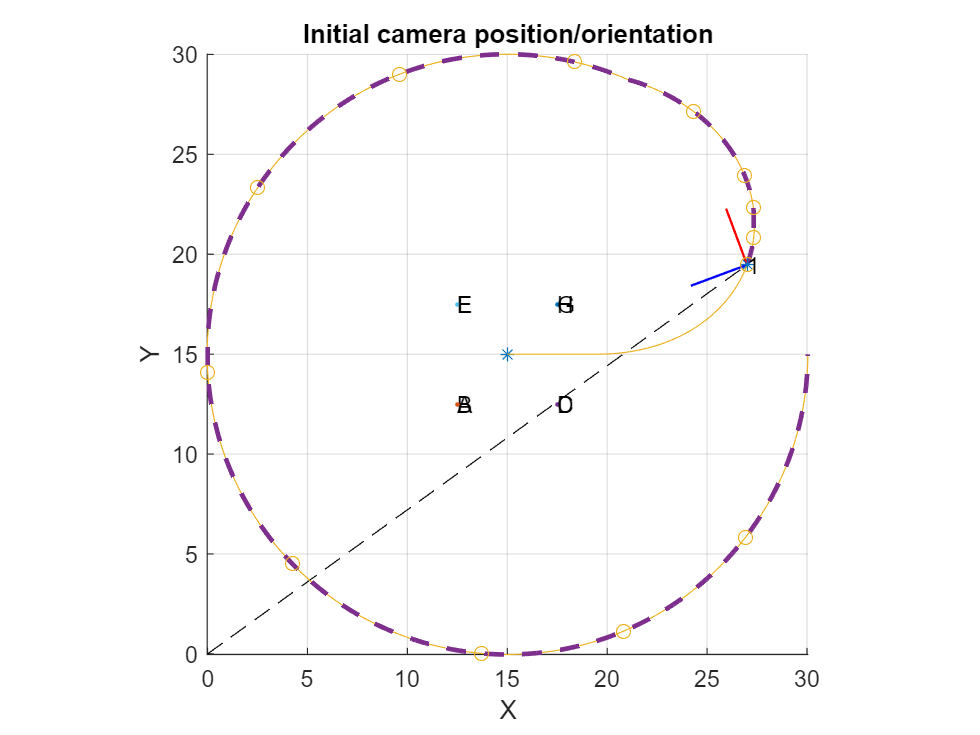

hold on
triad('Parent',gca,'Scale',3,'LineWidth',1,'Tag','#1','Matrix', [Rwb Twb; 0 0 0 1]);
scatter3(Twb(1), Twb(2), Twb(3), 'Marker',"*", 'HandleVisibility','off')
quiver3(0, 0, 0, Twb(1), Twb(2), Twb(3), "AutoscaleFactor", 1, 'HandleVisibility','off', 'Color', 'k', 'LineStyle','--', "ShowArrowHead", 'off');
scatter3(T_history_abs(1,:), T_history_abs(2,:), T_history_abs(3,:), "Marker", "o")
text(Twb(1), Twb(2), Twb(3), "1");
view(3)
zlim([0 15])
grid on
xlabel 'X'
ylabel 'Y'
zlabel 'Z'
title("Initial camera position/orientation");
view(2)

## Trajectory generation and plotting

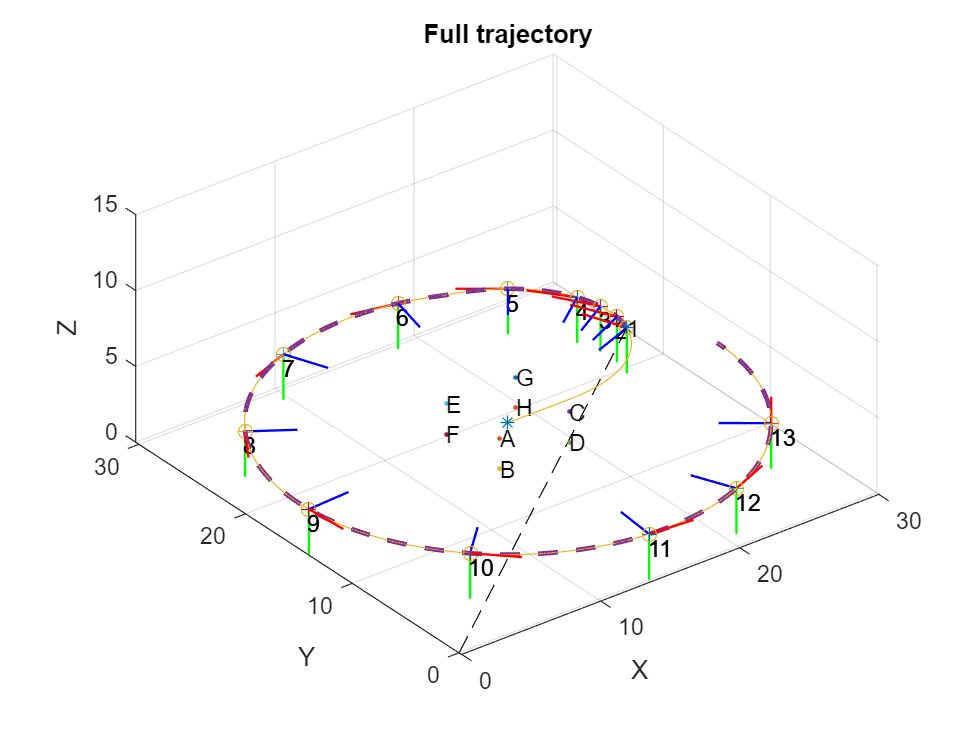

for i = 2:N
    R0i = R_history_abs(:,:,i);
    T0i = T_history_abs(:,i);
    triad('Parent',gca,'Scale',3,'LineWidth',1,'Tag',"#" + i ,'Matrix', [R0i T0i; 0 0 0 1]);
    scatter3(T0i(1) , T0i(2) , T0i(3) , 'Marker' , '+', 'HandleVisibility','off');
    text(T0i(1) - [0.5 0.5 0.5], T0i(2) - [0.5 0.5 0.5], T0i(3) - [0.5 0.5 0.5], "" + i);
    hold on
end

for i = 1:N
    if i == N
        j = 1;
    else
        j = i + 1;
    end
end
zlim([0 15])
view(3)
daspect([1 1 1])
grid on
xlabel 'X'
ylabel 'Y'
zlabel 'Z'
title("Full trajectory");

## Generate E from R and T (until we can figure out E estimation)

E_history = zeros(3,3,N,N); % create a cell array equal to the number of poses
EN_history = zeros(3,3,N,N); % same for noisy E
GT_rel_T = zeros(3,1,N,N);
GT_rel_T_norm = zeros(3,1,N,N);
GT_rel_R = zeros(3,3,N,N);

for i = 1:N
    for j = 1:N
        if j == i
            GT_rel_R(:,:, i, j) = eye(3);
            GT_rel_T(:,:, i, j) = zeros(3,1);
            continue
        else
            R_ij = axang2rotm([0 1 0 deg2rad(cam_angles(j) - cam_angles(i))]);
        end
        T_ij = T_history_abs(:, j) - T_history_abs(:, i);
        E = getSkew(T_ij) * R_ij;
        GT_rel_T(:,:, i, j) = T_ij;
        GT_rel_T_norm(:, :, i, j) = T_ij / norm(T_ij);
        GT_rel_R(:,:, i, j) = R_ij;
        E = E / norm(E); % normalize to lose scale
        E_noisy = E + gamma_E*rand(3, 3); % poison E matrix with noise to simulate reconstruction error
        E_history(:,:, i, j) = E;
        EN_history(:,:, i, j) = E_noisy;
    end
end

## Compute R, T from E

R1_rel = zeros(3,3,N,N);
T1_rel = zeros(3,1,N,N);
R2_rel = zeros(3,3,N,N);
T2_rel = zeros(3,1,N,N);

for i = 1:N
    for j = 1:N
        if i == j; continue; end
        %Compute R_ij and T_ij
        %E = E_history(:,:, i, j); % Extract E_ij
        E = EN_history(:,:, i, j); % Uncomment to to use noisy
        [U, S, V] = svd(E); % Singular value decomp
        % Safeguard against non SO(3) matrix
        if (det(U)<0)
            U = [U(:,1) U(:,2) -U(:,3)];
        end
        if (det(V)<0)
            V = [V(:,1) V(:,2) -V(:,3)]; 
        end
        sigmas = diag(S); % Get singular values
        avg = (sigmas(1) + sigmas(2)) / 2; % Average values
        sigmas = [avg; avg; 0]; % Substitute
        S = diag(sigmas);
        Rp = [cos(pi/2) -sin(pi/2) 0; sin(pi/2) cos(pi/2) 0; 0 0 1]; % Rotation of pi/2 around z axis
        Rm = [cos(-pi/2) -sin(-pi/2) 0; sin(-pi/2) cos(-pi/2) 0; 0 0 1]; % Rotation of -pi/2 around z axis
        skewT1 = U * Rp * S * U'; % Get T matrix
        currT1 = getT(skewT1); % Get T from T matrix
        currT2 = -getT(skewT1);
        currR1 = U * Rp' * V'; % Get R matrix
        currR2 = U * Rm' * V';
        R1_rel(:,:, i, j) = currR1; % Save data
        T1_rel(:,:, i, j) = currT1;
        R2_rel(:,:, i, j) = currR2;
        T2_rel(:,:, i, j) = currT2;
    end
end

## Perspective projection of points (photos simulation)

PI0 = [eye(3) zeros(3,1)]; % standard projection matrix
K_f = eye(3); % unitary focal length
K_s = [1 0 0; 0 1 0; 0 0 1]; % ideal, no distortion
K = K_s * K_f;
im_planes_norm = zeros(3, n_points, N); % normalized points for each view
im_planes_noisy = zeros(3, n_points, N); % noisy normalized points for each view (actual photos)
centers_norm = zeros(3, N);
centers_noisy = zeros(3,N);

for i = 1:N
    f = figure('name', "photo" + i);
    R0i = R_history_abs(:, :, i);
    T0i = T_history_abs(:, i);
    Ri0 = R0i';
    Ti0 = -T0i;
    g = [Ri0 Ri0*Ti0; 0 0 0 1];
    proj_c_og = K * PI0 * g * [center; 1];
    proj_c_norm = proj_c_og / proj_c_og(3);
    centers_norm(:, i) = proj_c_norm;
    centers_noisy(:, i) = proj_c_norm + [gamma_photo * rand(2,1); 0];
    scatter(proj_c_norm(1), proj_c_norm(2), 200, "Marker", "pentagram");
    text(proj_c_norm(1), proj_c_norm(2), "C", "Fontsize", 8, "HorizontalAlignment","center","FontWeight","bold");
    hold on
    grid on
    for j = 1:n_points
        im_point = K * PI0 * g * [points(:,j); 1];
        im_planes_norm(:, j, i) = im_point / im_point(3);
        im_planes_noisy(:, j, i) = im_point / im_point(3) + [gamma_photo*rand(2,1); 0];
        scatter(im_planes_noisy(1, j, i), im_planes_noisy(2, j, i), 36, "Marker", ".");
        scatter(im_planes_norm(1, j, i), im_planes_norm(2, j, i), 90, "Marker", "square");
        text(im_planes_norm(1, j, i), im_planes_norm(2, j, i), char('@'+ j), "Fontsize", 8, "HorizontalAlignment","center");
    end
    title("Image on pose #" + i);
    set(gca, 'YDir','reverse')
    close(f)
end

## Reconstruct camera center (beacon center) from center using all photos in single view (cuboid case)

est_dist = zeros(N,1);
for i = 1:N
    AB_3D = norm(points(:, 2) - points(:,1));
    CD_3D = norm(points(:, 4) - points(:,3));
    EF_3D = norm(points(:, 6) - points(:,5));
    GH_3D = norm(points(:, 8) - points(:,7));
    AB = norm(im_planes_noisy(:,2,i)- im_planes_noisy(:,1,i));
    CD = norm(im_planes_noisy(:,4,i)- im_planes_noisy(:,3,i));
    EF = norm(im_planes_noisy(:,6,i)- im_planes_noisy(:,5,i));
    GH = norm(im_planes_noisy(:,8,i)- im_planes_noisy(:,7,i));
    Z_AB = AB_3D / AB;
    Z_CD = CD_3D / CD;
    Z_EF = EF_3D / EF;
    Z_GH = GH_3D / GH;
    Z_CENTER = mean([Z_AB, Z_CD, Z_EF, Z_GH]);
    est_dist(i) = Z_CENTER;
end

est_r0 = mean(est_dist);
est_center = [x0; y0 + est_r0; z0];

## Pose discrimination via triangulation (!!! NOT WORKING AT ALL !!!)

cam = cameraParameters("IntrinsicMatrix", K);
R_rel = zeros(3,3,N,N);
T_rel = zeros(3,1,N,N);
for i = 1:N
    for j = 1:N
        if i == j
            R_rel(:, :, i, j) = eye(3);
            R1_rel(:, :, i, j) = eye(3);
            R2_rel(:, :, i, j) = eye(3);
            T_rel(:, :, i, j) = zeros(3,1);
            T1_rel(:, :, i, j) = zeros(3,1);
            T2_rel(:, :, i, j) = zeros(3,1);
            continue
        end
        best = 0;
        % Case 1 R1 T1
        % Extract R12 and T12 matrices
        R = R1_rel(:,:, i, j);
        T = T1_rel(:,:, i, j);
        % Configure foward extrinsic
        P1 = K * PI0 * [eye(3) zeros(3,1); 0 0 0 1];
        P2 = K * PI0 * [R' -R' * T; 0 0 0 1];
        % Triangulate points in frame 1
        pnts = triangulate(im_planes_norm(1:2,:,i)', im_planes_norm(1:2,:,j)', P1', P2');
        % Count positive occurences in z for both
        votes = nnz((double(pnts(:,3)) > 0) == 1);
        % If better result than previous
        if votes > best
            % Update best result
            best = votes;
            %fprintf("Filled cell [%i,%i] with %i/%i votes\n", i, j, best, n_points);
            % Save R12, T12 as correct
            R_rel(:,:, i, j) = R;
            T_rel(:,:, i, j) = T;
        end
        % Case 2 R1 T2
        R = R1_rel(:,:, i, j);
        T = T2_rel(:,:, i, j);
        P1 = K * PI0 * [eye(3) zeros(3,1); 0 0 0 1];
        P2 = K * PI0 * [R' -R' * T; 0 0 0 1];
        % Triangulate points in frame
        pnts = triangulate(im_planes_norm(1:2,:,i)', im_planes_norm(1:2,:,j)', P1', P2');
        % Count positive occurences in z for both
        votes = nnz((double(pnts(:,3)) > 0) == 1);
        if votes > best
            best = votes;
            %fprintf("Filled cell [%i,%i] with %i/%i votes\n", i, j, best, n_points);
            R_rel(:,:, i, j) = R;
            T_rel(:,:, i, j) = T;
        end
        % Case 3 R2 T1
        R = R2_rel(:,:, i, j);
        T = T1_rel(:,:, i, j);
        P1 = K * PI0 * [eye(3) zeros(3,1); 0 0 0 1];
        P2 = K * PI0 * [R' -R' * T; 0 0 0 1];
        % Triangulate points in frame
        pnts = triangulate(im_planes_norm(1:2,:,i)', im_planes_norm(1:2,:,j)', P1', P2');
        % Count positive occurences in z for both
        votes = nnz((double(pnts(:,3)) > 0) == 1);
        if votes > best
            best = votes;
            %fprintf("Filled cell [%i,%i] with %i/%i votes\n", i, j, best, n_points);
            R_rel(:,:, i, j) = R;
            T_rel(:,:, i, j) = T;
        end
        % Case 4 R2 T2
        R = R2_rel(:,:, i, j);
        T = T2_rel(:,:, i, j);
        P1 = K * PI0 * [eye(3) zeros(3,1); 0 0 0 1];
        P2 = K * PI0 * [R' -R' * T; 0 0 0 1];
        % Triangulate points in frame
        pnts = triangulate(im_planes_norm(1:2,:,i)', im_planes_norm(1:2,:,j)', P1', P2');
        % Count positive occurences in z for both
        votes = nnz((double(pnts(:,3)) > 0) == 1);
        if votes > best
            best = votes;
            %fprintf("Filled cell [%i,%i] with %i/%i votes\n", i, j, best, n_points);
            R_rel(:,:, i, j) = R;
            T_rel(:,:, i, j) = T;
        end
    end
end

## Discriminate pose manually

for i = 1:N
    for j = 1:N
        R1 = R1_rel(:,:,i,j);
        R2 = R2_rel(:,:,i,j);
        RGT = GT_rel_R(:,:,i,j);
        if norm(R1 - RGT) >= norm(R2 - RGT)
            R_rel(:,:,i,j) = R2;
        else
            R_rel(:,:,i,j) = R1;
        end
        T1 = T1_rel(:,:,i,j);
        T2 = T2_rel(:,:,i,j);
        TGT = GT_rel_T_norm(:,:,i,j);
        if norm(T1 - TGT) >= norm(T2 - TGT)
            T_rel(:,:,i,j) = T2;
        else
            T_rel(:,:,i,j) = T1;
        end
    end
end

## Sanity check

% Take only first row for each table
est_T = reshape(T_rel(:,:,1,:), 3, N);
est_T1 = reshape(T1_rel(:,:,1,:), 3, N);
est_T2 = reshape(T2_rel(:,:,1,:), 3, N);
T = reshape(GT_rel_T_norm(:,:,1,:), 3, N);
%wrong1 = abs(est_T1 - T) > 1e-1
%wrong2 = abs(est_T2 - T) > 1e-1
wrongfT = abs(est_T - T) > 1e-1;
a1 = zeros(N,N);
a2 = zeros(N,N);
af = zeros(N,N);
aGT = zeros(N,N);

for i = 1:N
    for j = 1:N
        a1(i,j) = getYangle(R1_rel(:,:,i,j));
        a2(i,j) = getYangle(R2_rel(:,:,i,j));
        af(i,j) = getYangle(R_rel(:,:,i,j));
        aGT(i,j) = getYangle(GT_rel_R(:,:,i,j));
    end
end

%wrong1 = abs(a1 - aGT) > 5;
%wrong2 = abs(a2 - aGT) > 5;
wrongfR = abs(af - aGT) > 5;

if ~(wrongfT > 0)
    disp("Correct T discrimination")
else
    disp("Not within margin of error")
end

Correct T discrimination


if ~(wrongfR > 0)
    disp("Correct R discrimination")
else 
    disp("Not within margin of error")
end

Not within margin of error


af

af =          0   -3.3485   -8.9581  -14.2427  -30.8191  -53.7217  -89.6430 -124.2214 -162.3104  158.3028  115.5655   88.0199   57.4953
    4.3509         0   -4.7966   -9.5362  -25.7558  -52.4654  -83.4346 -117.5305 -156.0557  164.0562  122.8006   92.6827   62.5113
    8.2532    4.3606         0   -5.3658  -18.6336  -43.2293  -78.4739 -114.8467 -149.0682  169.1265  127.4750   98.7359   67.9156
   15.8459   11.0329    4.8710         0  -13.3319  -37.4149  -70.6578 -107.8683 -143.8130  177.1518  134.5132  105.1238   73.7897
   30.6944   26.2493   22.3157   12.9637         0  -21.9859  -55.1710  -88.5000 -128.0519 -170.2024  149.8761  119.9077   90.8010
   57.3562   51.8983   45.2308   38.7411   23.5707         0  -31.2643  -68.4445 -106.2695 -144.7424  173.5308  145.6918  115.9714
   90.7938   87.0153   82.6049   74.0660   59.2419   32.5488         0  -33.1547  -72.3350 -113.7759 -152.3953  178.8569  151.3443
  129.0906  120.9234  115.6943  108.4730   94.3356   67.4877   36.3024        

aGT

aGT =          0   -4.8696  -10.3899  -16.6088  -32.0239  -56.6970  -90.5624 -125.7640 -163.0131  156.1468  115.4498   87.6756   58.0084
    4.8696         0   -5.5204  -11.7392  -27.1543  -51.8274  -85.6928 -120.8944 -158.1435  161.0164  120.3193   92.5452   62.8780
   10.3899    5.5204         0   -6.2188  -21.6339  -46.3070  -80.1725 -115.3741 -152.6232  166.5367  125.8397   98.0655   68.3984
   16.6088   11.7392    6.2188         0  -15.4151  -40.0882  -73.9536 -109.1552 -146.4043  172.7556  132.0585  104.2844   74.6172
   32.0239   27.1543   21.6339   15.4151         0  -24.6731  -58.5386  -93.7402 -130.9892 -171.8293  147.4736  119.6995   90.0323
   56.6970   51.8274   46.3070   40.0882   24.6731         0  -33.8654  -69.0670 -106.3161 -147.1562  172.1467  144.3726  114.7054
   90.5624   85.6928   80.1725   73.9536   58.5386   33.8654         0  -35.2016  -72.4507 -113.2908 -153.9878  178.2380  148.5708
  125.7640  120.8944  115.3741  109.1552   93.7402   69.0670   35.2016       

abs(af - aGT)

ans =          0    1.5211    1.4319    2.3661    1.2047    2.9752    0.9194    1.5426    0.7027    2.1560    0.1158    0.3443    0.5131
    0.5187         0    0.7237    2.2030    1.3985    0.6380    2.2582    3.3640    2.0879    3.0398    2.4812    0.1375    0.3667
    2.1367    1.1598         0    0.8530    3.0003    3.0778    1.6986    0.5274    3.5550    2.5898    1.6353    0.6704    0.4827
    0.7629    0.7063    1.3478         0    2.0832    2.6733    3.2958    1.2870    2.5913    4.3962    2.4547    0.8395    0.8275
    1.3295    0.9050    0.6817    2.4514         0    2.6872    3.3676    5.2401    2.9374    1.6269    2.4024    0.2083    0.7687
    0.6592    0.0709    1.0763    1.3471    1.1024         0    2.6012    0.6225    0.0466    2.4138    1.3841    1.3192    1.2660
    0.2314    1.3225    2.4324    0.1123    0.7033    1.3167         0    2.0469    0.1157    0.4851    1.5925    0.6189    2.7734
    3.3265    0.0289    0.3202    0.6822    0.5955    1.5793    1.1008       

## Filter R

%% Initial filtering of T based on the fact that we expect a symmetric table
up = triu(af);
low = -tril(af)';
tot = (up + low) / 2;
af = tot - tot'

af =          0   -3.8497   -8.6057  -15.0443  -30.7568  -55.5390  -90.2184 -126.6560 -161.9778  157.9584  115.8787   87.8053   57.8645
    3.8497         0   -4.5786  -10.2845  -26.0026  -52.1818  -85.2250 -119.2269 -156.1199  164.1682  122.2858   92.3092   62.0476
    8.6057    4.5786         0   -5.1184  -20.4746  -44.2300  -80.5394 -115.2705 -150.1753  168.5000  127.3094   98.3161   67.6553
   15.0443   10.2845    5.1184         0  -13.1478  -38.0780  -72.3619 -108.1706 -144.4584  175.5661  133.9723  104.7486   74.2184
   30.7568   26.0026   20.4746   13.1478         0  -22.7783  -57.2064  -91.4178 -128.3225 -169.8697  149.0331  120.1555   90.3321
   55.5390   52.1818   44.2300   38.0780   22.7783         0  -31.9065  -67.9661 -105.4886 -145.2840  173.4496  145.9419  115.4464
   90.2184   85.2250   80.5394   72.3619   57.2064   31.9065         0  -34.7286  -72.2448 -113.5182 -152.4424  178.7626  150.5062
  126.6560  119.2269  115.2705  108.1706   91.4178   67.9661   34.7286        

## Scale T_rel

T_scaled_rel = zeros(3,1,N,N);
for i = 1:N
    for j = 1:N
        % Cosine theorem
        c = sqrt(est_dist(i) ^ 2 + est_dist(j) ^ 2 - 2 * est_dist(i) * est_dist(j) * cos(deg2rad(af(i,j))));
        T_scaled_rel(:,:,i,j) = c * T_rel(:,:,i,j);
    end
end

## Filter T

%% Initial filtering of T based on the fact that we expect a symmetric table
TX = reshape(T_scaled_rel(1, :, :, :), N, N);
TXU = triu(TX);
TXL = tril(TX);
TXU = (TXU - TXL') / 2;
TXL = -TXU';
TX = TXU + TXL;
TY = reshape(T_scaled_rel(2, :, :, :), N, N);
TYU = triu(TY);
TYL = tril(TY);
TYU = (TYU - TYL') / 2;
TYL = -TYU';
TY = TYU + TYL;
TX = reshape(TX, 1, 1, N, N);
TY = reshape(TY, 1, 1, N, N);
T_scaled_rel(1, :, :, :) = TX;
T_scaled_rel(2, :, :, :) = TY;
reshape(T_scaled_rel(1:2, :, :, :), 2*N, N)

ans =          0    0.2995    0.2924    0.0081   -2.4713   -8.2743  -16.9275  -24.7728  -26.7575  -23.1091  -14.2769   -7.0992   -0.3244
         0    1.2659    2.6314    4.0522    7.3858    9.9356    8.8540    3.4695   -6.0002  -14.6767  -18.9845  -17.7418  -13.3873
   -0.2995         0   -0.0385   -0.3525   -2.8360   -8.9296  -17.4394  -24.5170  -27.4801  -23.4895  -14.0143   -7.1132   -0.6639
   -1.2659         0    1.3627    2.6923    6.0242    8.9660    7.6606    1.8669   -7.1297  -16.4204  -20.5617  -19.1554  -14.6029
   -0.2924    0.0385         0   -0.3219   -2.7896   -8.7014  -17.6102  -25.0013  -26.9754  -23.6143  -14.5719   -7.0658   -0.9598
   -2.6314   -1.3627         0    1.2937    4.5621    6.8722    6.2720    0.9728   -9.1265  -17.4800  -21.6294  -20.7137  -16.2156
   -0.0081    0.3525    0.3219         0   -2.1766   -7.9881  -16.8027  -24.2530  -26.4189  -22.5988  -13.7549   -6.5689   -0.0660
   -4.0522   -2.6923   -1.2937         0    2.7394    5.3291    4.4365   -0.8

## Plot T

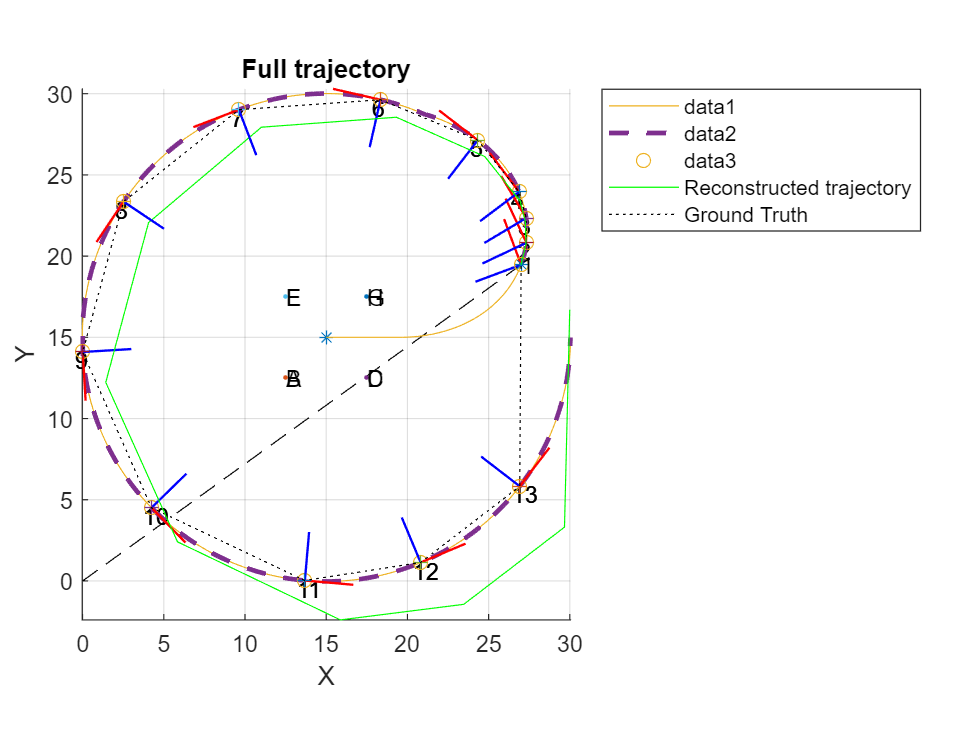

est_traj = zeros(3, N + 1);
corrected_est_traj = zeros(3, N + 1);
corrected_est_traj(:, 1) = Twb;
currP = Twb;
for i = 1:N
    if i == N
        j = 1;
    else 
        j = i + 1;
    end
    nextP = currP + T_scaled_rel(:,:,i, j);
    corrected_est_traj(:, i + 1) = nextP;
    currP = nextP;
end

%% Plot trajectory
T_history_abs = [T_history_abs T_history_abs(:, 1)];
figure(fig)
set(0,'CurrentFigure',fig)
hold on
plot3(corrected_est_traj(1, :), corrected_est_traj(2, :), corrected_est_traj(3, :), "DisplayName", "Reconstructed trajectory", "Color", "g")
plot3(T_history_abs(1, :), T_history_abs(2, :), T_history_abs(3, :), "DisplayName", "Ground Truth", "Color", "k", "Linestyle", ":")
legend
view(2)

## Functions

function alpha = getYangle(R)
    alpha = wrapTo180(rad2deg(atan2(R(3,1), R(1,1))));
end

function R = getRfromZ(T, center)
    z_versor = center - T;
    z_versor = z_versor / norm(z_versor);
    y_versor = [0 0 -1];
    x1_versor = cross(y_versor, z_versor);
    r11 = dot(x1_versor, [1 0 0]);
    r21 = dot(x1_versor, [0 1 0]);
    r31 = dot(x1_versor, [0 0 1]);
    r12 = dot(y_versor, [1 0 0]);
    r22 = dot(y_versor, [0 1 0]);
    r32 = dot(y_versor, [0 0 1]);
    r13 = dot(z_versor, [1 0 0]);
    r23 = dot(z_versor, [0 1 0]);
    r33 = dot(z_versor, [0 0 1]);
    R = [r11 r12 r13; r21 r22 r23; r31 r32 r33];
end